%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms u

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=4*(0.3960*cos(2.65*(u+1.4)));
rj=4*(-0.99*sin(u+1.4));
rk=0*u;
r=[ri,rj,rk];

%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,u);

%you will see that the unit tangent vector is a
%bit difficult to read and the algebra doesn't seem to be simplified
%(note I use the norm function, not abs)
T_hat_ugly=dr./norm(dr)

$$T\_hat\_ugly = \begin{array}{l} \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{1250\,\sigma_{1}} & -\frac{99\,\cos\left(u+\frac{7}{5}\right)}{25\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{27531009\,{\left|\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)\right|}^{2}}{1562500}+\frac{9801\,{\left|\cos\left(u+\frac{7}{5}\right)\right|}^{2}}{625}} \end{array}$$


% we want to add some assumptions so that the algebra simplifies the way it
% should
assume(u,'real') % parameter u should be real

%now we can use the simplify function to make things look nice
T_hat=simplify(T_hat_ugly)

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(u+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}^{2}} \end{array}$$


%Next, we want to find the unit normal vector
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(483625\,\sigma_{6}+702250\,\sigma_{5}+218625\,\sigma_{4}\right)}{\sigma_{1}} & \frac{561800\,\sin\left(u+\frac{7}{5}\right)+1025285\,\sigma_{3}+463485\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=265\,\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}+2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,u}{20}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right) \end{array}$$


%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

$$B\_hat = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{91250\,\cos\left(\frac{7\,u}{20}+\frac{49}{100}\right)+\frac{764917\,\cos\left(\frac{33\,u}{20}+\frac{231}{100}\right)}{2}+\frac{327837\,\cos\left(\frac{73\,u}{20}+\frac{511}{100}\right)}{2}+41250\,\cos\left(\frac{113\,u}{20}+\frac{791}{100}\right)-\frac{205057\,\cos\left(\frac{139\,u}{20}+\frac{973}{100}\right)}{2}-\frac{92697\,\cos\left(\frac{179\,u}{20}+\frac{1253}{100}\right)}{2}}{\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\right)}^{2}+2500\,{\left(73\,\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\right)}^{2}}\,\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\sigma_{1}\right)}^{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{53\,u}{20}+\frac{371}{100} \end{array}$$


%We can also find the curvature
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa)

$$kappa = \begin{array}{l} \frac{165625\,\sqrt{2}\,\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\right)}^{2}+2500\,{\left(73\,\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\right)}^{2}}}{198\,\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\sigma_{1}\right)}^{2}}\,{\left(2500\,\cos\left(2\,u+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,u}{10}+\frac{371}{50}\right)+5309\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{53\,u}{20}+\frac{371}{100} \end{array}$$


%How about the Torsion?
tau=-dot(N_hat,(diff(B_hat,u)/norm(dr)))

$$tau = 0$$

21.1

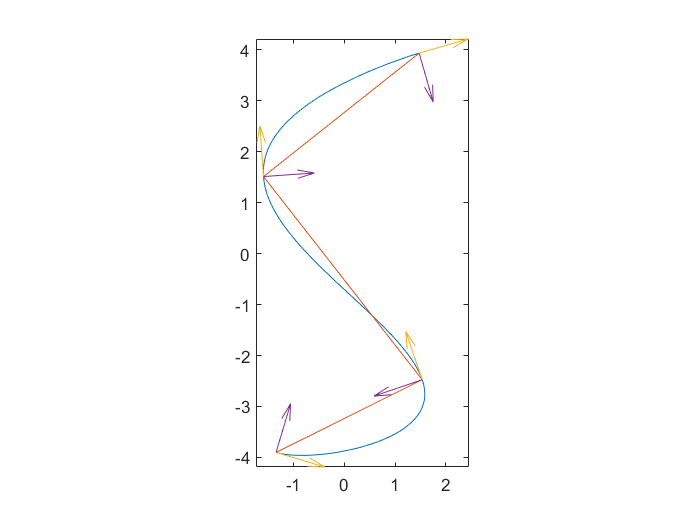

% Plot parametric curve
u_points = linspace(0,3.2,4);
T_hat_values = subs(T_hat',u,u_points);
N_hat_values = subs(N_hat',u,u_points);
xy_points = subs(r',u,u_points);

clf
fplot(ri,rj,[0,3.2])
axis equal
hold on
plot((xy_points(1,:))',(xy_points(2,:)'))
quiver(xy_points(1,:)',xy_points(2,:)',T_hat_values(1,:)',T_hat_values(2,:)', 0);
quiver(xy_points(1,:)',xy_points(2,:)',N_hat_values(1,:)',N_hat_values(2,:)', 0);

21.2

syms t
rt = subs(r, u, t)

$$rt = \left(\begin{array}{ccc} \frac{198\,\cos\left(\frac{53\,t}{20}+\frac{371}{100}\right)}{125} & -\frac{99\,\sin\left(t+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$

linear_speed = norm(diff(rt, t))

$$linear\_speed = \sqrt{\frac{27531009\,{\left|\sin\left(\frac{53\,t}{20}+\frac{371}{100}\right)\right|}^{2}}{1562500}+\frac{9801\,{\left|\cos\left(t+\frac{7}{5}\right)\right|}^{2}}{625}}$$

T_hat_t = diff(rt, t)/norm(diff(rt, t));
dTdt = diff(T_hat_t, t);
angular_velocity = cross(T_hat_t, dTdt)

$$angular\_velocity = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{99\,\sigma_{5}\,\left(\frac{278091\,\sigma_{3}}{25000\,\sqrt{\sigma_{2}}}-\frac{5247\,\sigma_{4}\,\sigma_{1}}{2500\,{\sigma_{2}}^{3/2}}\right)}{25\,\sqrt{\sigma_{2}}}-\frac{5247\,\sigma_{4}\,\left(\frac{99\,\sin\left(t+\frac{7}{5}\right)}{25\,\sqrt{\sigma_{2}}}+\frac{99\,\sigma_{5}\,\sigma_{1}}{50\,{\sigma_{2}}^{3/2}}\right)}{1250\,\sqrt{\sigma_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1459143477\,\left|\sigma_{4}\right|\,\mathrm{sign}\left(\sigma_{4}\right)\,\sigma_{3}}{15625000}-\frac{19602\,\sin\left(t+\frac{7}{5}\right)\,\left|\sigma_{5}\right|\,\mathrm{sign}\left(\sigma_{5}\right)}{625}\\ \sigma_{2}=\frac{27531009\,{\left|\sigma_{4}\right|}^{2}}{1562500}+\frac{9801\,{\left|\sigma_{5}\right|}^{2}}{625}\\ \sigma_{3}=\cos\left(\frac{53\,t}{20}+\frac{371}{100}\right)\\ \sigma_{4}=\sin\left(\frac{53\,t}{20}+\frac{371}{100}\right)\\ \sigma_{5}=\cos\left(t+\frac{7}{5}\right) \end{array}$$

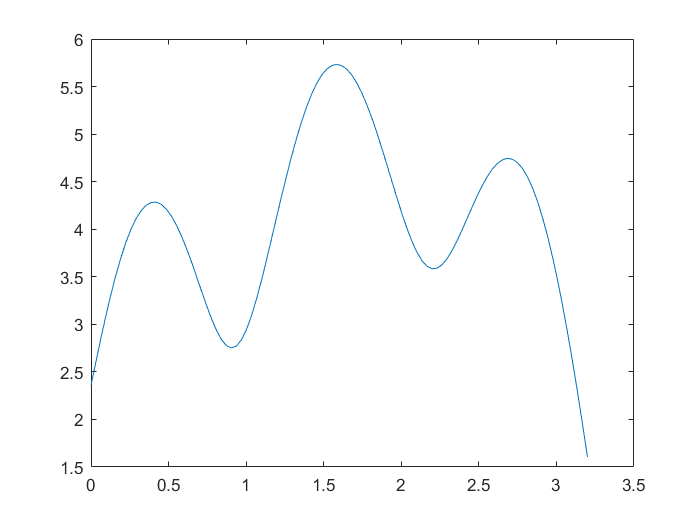



t_points = linspace(0,3.2, 100);

linear_speed_points = subs(linear_speed, t, t_points);
angular_velocity_points = subs(angular_velocity, t, t_points);
clf
plot(t_points, linear_speed_points')

plot(t_points, angular_velocity_points')

Error using plot
Vectors must be the same length.